A perfume bottle opened inside a classroom releases fragrance throughtout the room because the molecules evaporate from the bottle and then collides randomly with other air moelcules. We develop a model for this process as the basis for a computer simulation of a random walk. The fragrance travels randomly because the chance of collision will determine the path it takes and it requires a number amount of steps for the molecules to travel from the intital point to its destinational point. 

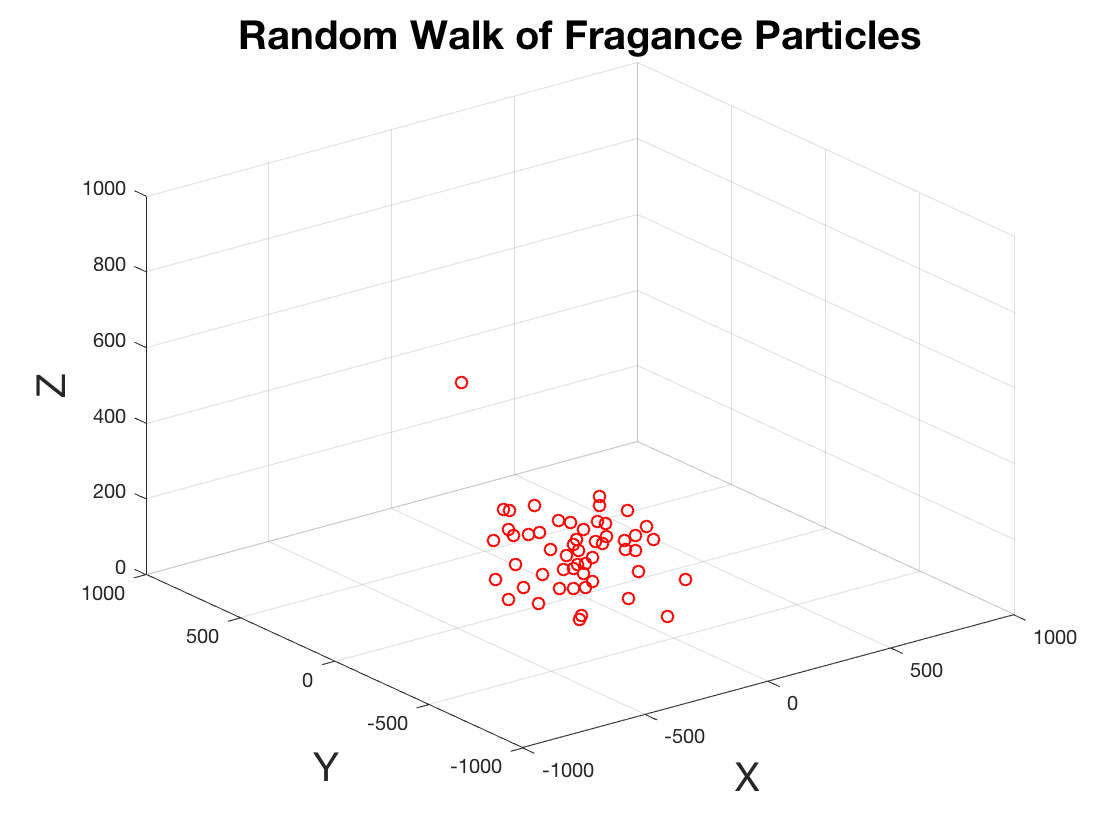

clc;    % Clear the command window.
clearvars;
close all; 

fontsize = 20;

NWalkers = 100;
dx = 10;
dy = 10;
dz = 10;
NTimeSteps = 500;
Xi = -1000;
Yi = 0;
Zi = 1000;

x = zeros(1,NWalkers);
y = x;
z = y;

x(1) = Xi;
y(1) = Yi;
z(1) = Zi;

for i = 1:NTimeSteps
    for j = 1:length(x)
    a = rand;
        if (a <= 1/6)
            x(j) = x(j) + dx;
        elseif (a <= 2/6 && a > 1/6)
            x(j) = x(j) - dx;
        elseif (a <= 3/6 && a > 2/6)
            y(j) = y(j) + dy;
        elseif (a <= 4/6 && a > 3/6)
            y(j) = y(j) - dy;
        elseif (a <= 5/6 && a > 4/6)
            z(j) = z(j) + dz;
        else
            z(j) = z(j) - dz;
        end 
    end
 figure(1) 
 pause(.01)
 h(i) = scatter3(x,y,z,'red');
 axis([-1000 1000 -1000 1000 0 1000]);
 title('Random Walk of Fragance Particles', 'fontsize', fontsize);
 xlabel('X','fontsize', fontsize);
 ylabel('Y','fontsize', fontsize);
 zlabel('Z','fontsize', fontsize);
 %drawnow
 hold off

end

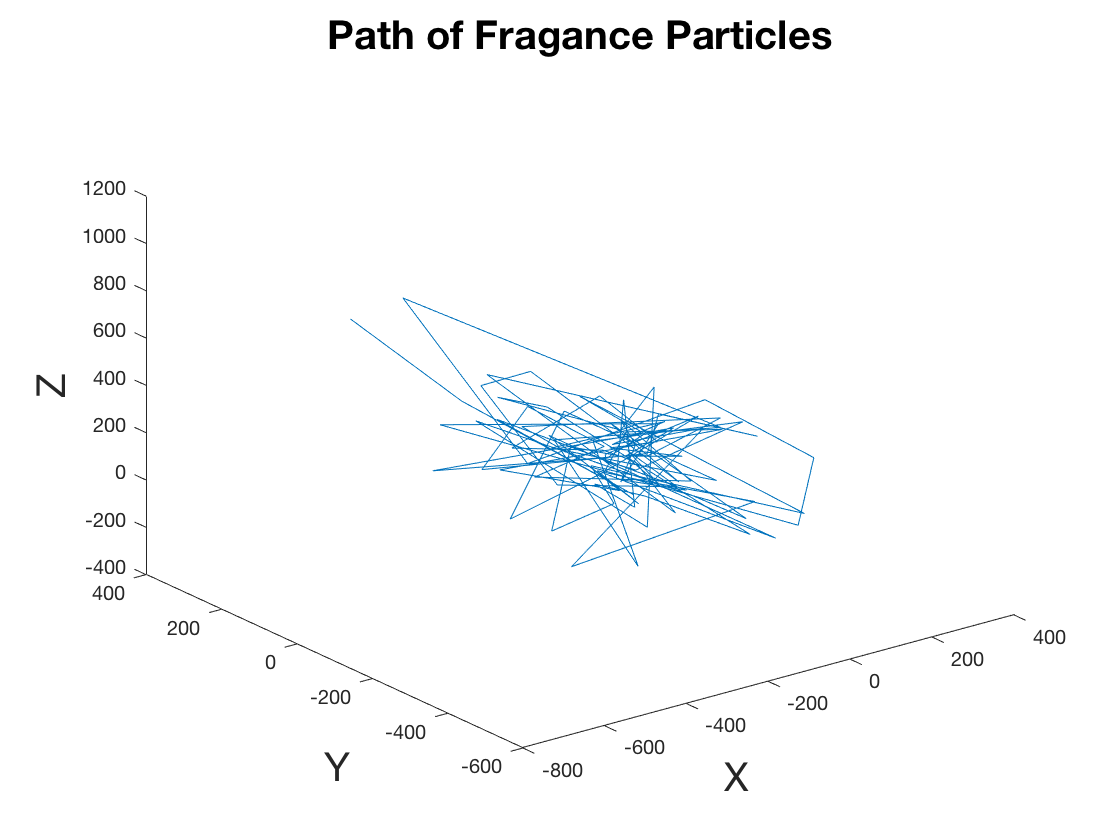

%Path followed  
figure(2)
plot3(x,y,z);
title('Path of Fragance Particles', 'fontsize', fontsize);
xlabel('X','fontsize', fontsize);
ylabel('Y','fontsize', fontsize);
zlabel('Z','fontsize', fontsize);

 Some appropriate rules for the walkers to follow and justify those rules.....					

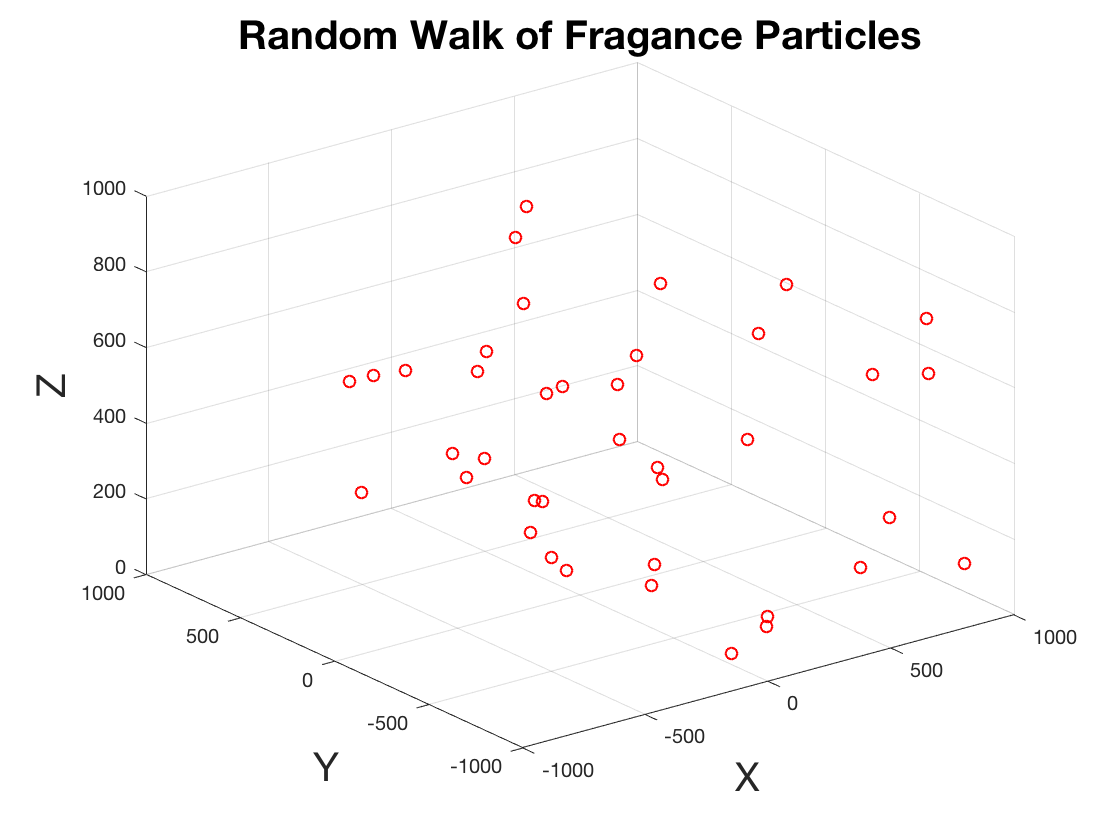

figure(3)
RandomWalk(500,50,100,100,1000,1000,1,2,3,4,5,-1000,0,1000)
title('Random Walk of Fragance Particles', 'fontsize', fontsize);
xlabel('X','fontsize', fontsize);
ylabel('Y','fontsize', fontsize);
zlabel('Z','fontsize', fontsize);

We assume that a particle (walker) takes N number of steps, with the direction of each step independent of the direction of the previous step. As seen in Figures 2 and 4, the walker starts at the origin and take N steps in the x-y-z plane, each of length delta x , y or z.  	

I would like to find the average distance (or mean) of the particle form initial to final postition, denoted by thr variable S

% 3D 
fontSize = 20;
%format compact;

numberOfSteps = 15;
tic
deltax = rand(numberOfSteps) - 0.5;
deltay = rand(numberOfSteps) - 0.5;
deltaz = rand(numberOfSteps) - 0.5;
xy = zeros(numberOfSteps,3);
for step = 2 : numberOfSteps
	% Walk in the x direction.
	xy(step, 1) = xy(step, 1) + deltax(step);	
	% Walk in the y direction.
	xy(step, 2) = xy(step, 2) + deltay(step);
        % walk in the z direction
        xy(step, 3) = xy(step, 3) + deltaz(step);
	% Now plot the walk so far.
	xCoords = xy(1:step, 1);
	yCoords = xy(1:step, 2);
        zCoords = xy(1:step, 3);
        drawnow
        figure(4)
	plot3(xCoords, yCoords, zCoords,'bo-', 'LineWidth', 2);
%         axis([-100 100 -100 100 0 100]);
        hold off;

end
toc

Elapsed time is 0.894639 seconds.


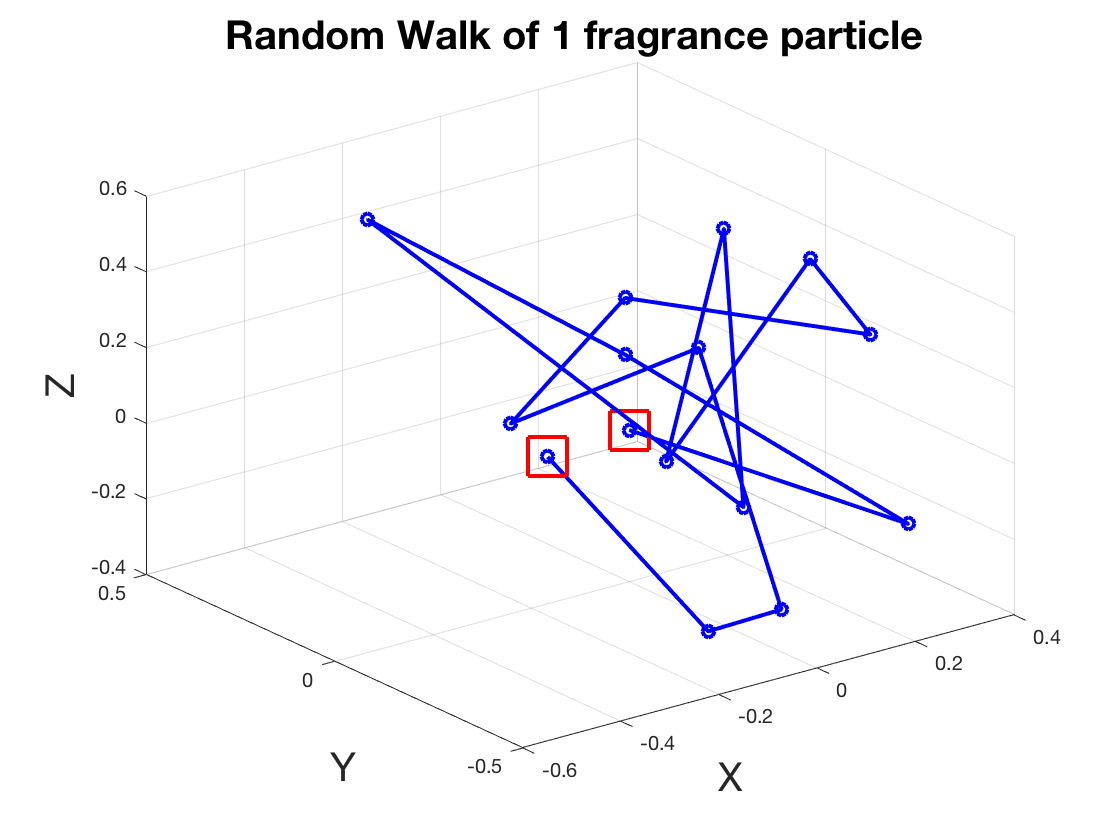

 % Mark the first point in red.
 hold on;
 plot3(xy(1,1), xy(1,2), xy(1,3), 'rs', 'LineWidth', 2, 'MarkerSize', 25);
 grid on;
 % Mark the last point in red.
 plot3(xCoords(end), yCoords(end), zCoords(end),'rs', 'LineWidth', 2, 'MarkerSize', 25);
 % make graph pretty 
 title('Random Walk of 1 fragrance particle ', 'FontSize', fontSize);
 xlabel('X', 'FontSize', fontSize);
 ylabel('Y', 'FontSize', fontSize);
 zlabel('Z', 'FontSize', fontSize);


% % Calculate the distance from the origin.
% distanceFromOrigin = hypot(xCoords(end), yCoords(end));
% message = sprintf('Distance of endpoint from origin = %.3f', distanceFromOrigin);
% msgbox(message);

A = [xCoords; yCoords; zCoords];
S = std(A)

S = 0.2798

% the spread of the particles is small due to small axis and delta step sizes. 


The random walk of the perfume particle used here is an example of a descret random process. The illustration is a very simple example of a random walk, more various conditions can be imposed on the motion of the particles. However, in our case we made everything else fixed, for example temperature, speed, pressure and other varibales involved in the system of fragance diffusion

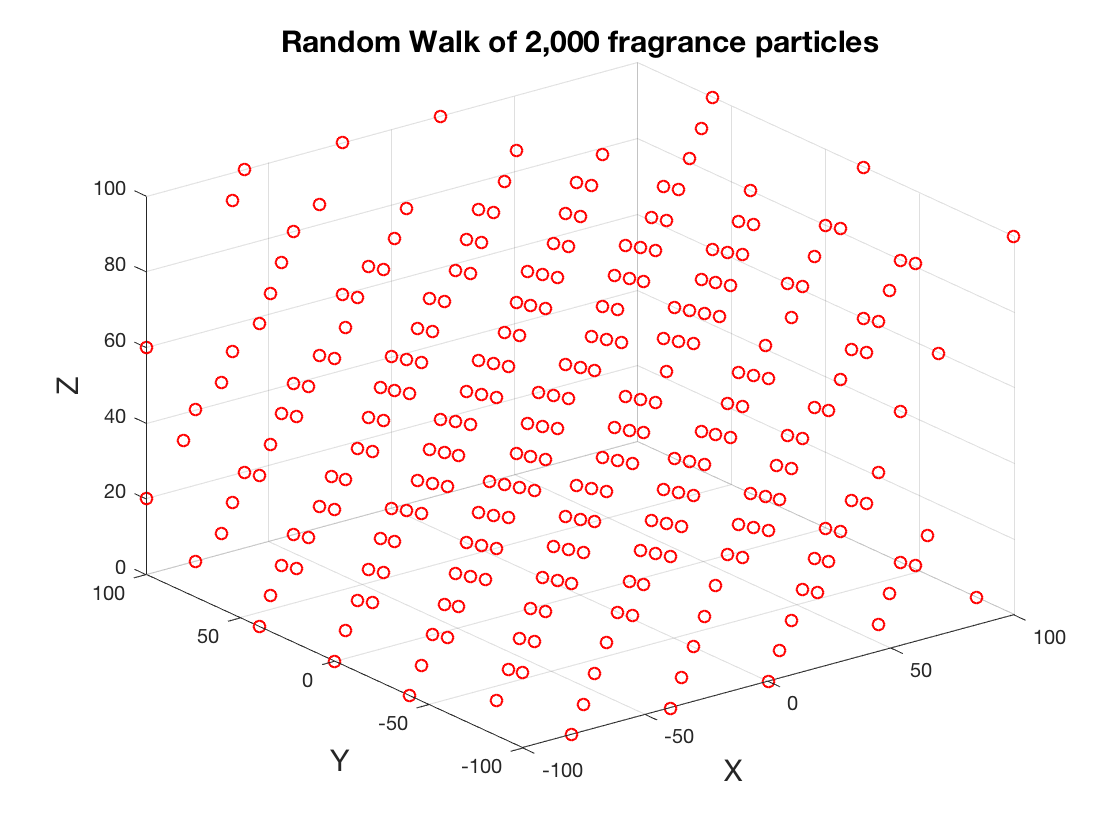

figure(7)
fontSize = 15;
RandomWalk(2000,20,20,20,25,100,1,2,3,4,5,-100,0,100)
title('Random Walk of 2,000 fragrance particles', 'FontSize', fontSize);
xlabel('X', 'FontSize', fontSize);
ylabel('Y', 'FontSize', fontSize);
zlabel('Z', 'FontSize', fontSize);

We can see that if we input the numbers of walkers and steps bigger enough, the molecule will release in the room like a uniform distribution. And the animation shows that how the molecule goes uniform. 

What we do wrong? The motion of molecule also should obey the Brownian motion which tell us that the motion of the pollen or dust results from their collisions with the liquid's molecules. However, the code we have assume that all molecules do not have collision volume, they can pass through each other without having collision. 

But since we igron the collision between molecules, we can think they follow the ideal gas rule which shows that $T=\frac{mv^2}{3k}$ where T is temperature, m is mass, v is velocity and k is Boltzmann constant, and this shows that the molecules will always move uniform distribution as long as the temperature is not absloute 0, the number of molecules and the time is enough.